# PID Controller Tuning

Lets you create a mathematical model of the system based on sampled data and tune a PID controller for it.

## System Identification

The model is identified from sampled data with an [Autoregressive Exogenous model](https://apmonitor.com/dde/index.php/Main/AutoRegressive).

% Dataset selection (time, input, output columns)
dataset = "/Users/valeriynovytskyy/Desktop/system-identification/rotation1.csv";

% Time range selection (seconds)
startTime = 70;
endTime = 120;

% Gaussian filter for measurements
smoothing = 32;

% Model parameters
numberOfStates = 2;
numberOfInputs = 2;
delayTimeSteps = 1;

% Load data
data = readtable(dataset);
time = data{:, 1};
inputs = data{:, 2};
measurements = data{:, 3};

% Resample to fixed timestep
[uniqueTime, ~, idx] = unique(time);
resampledTime = uniqueTime;
resampledInputs = accumarray(idx, inputs, [], @mean);
resampledMeasurements = accumarray(idx, measurements, [], @mean);
dt = mean(diff(resampledTime));
resampledStart = min(resampledTime);
resampledEnd = max(resampledTime);
regularTime = resampledStart:dt:resampledEnd;
inputs = interp1(resampledTime, resampledInputs, regularTime, 'linear', 'extrap');
measurements = interp1(resampledTime, resampledMeasurements, regularTime, 'linear', 'extrap');
time = regularTime;

% Select time range
mask = (time >= startTime) & (time <= endTime);
time = time(mask);
inputs = inputs(mask);
measurements = measurements(mask);

% Apply gaussian filter
if smoothing > 0
    measurements = smoothdata(measurements, 'gaussian', smoothing);
end

% Estimate model
measurements = measurements(:);
inputs = inputs(:);
numberOfSamples = numel(measurements);
maxDelay = max(numberOfStates, numberOfInputs + delayTimeSteps);
numberOfParameters = numberOfStates + (numberOfInputs + 1);
numberOfRows = numberOfSamples - maxDelay;
samplesMatrix = zeros(numberOfRows, numberOfParameters);

% State transition: -y[k-1], -y[k-2], ..., -y[k-numberOfStates]
for j = 1:numberOfStates
    samplesMatrix(:, j) = -measurements((maxDelay - j + 1) : (numberOfSamples - j));
end

% Input mapping: u[k-delay], u[k-delay-1], ..., u[k-delay-numberOfInputs]
for j = 0:numberOfInputs
    samplesMatrix(:, numberOfStates + 1 + j) = ...
        inputs((maxDelay - delayTimeSteps - j + 1) : (numberOfSamples - delayTimeSteps - j));
end

% Target vector corresponds to y[k] for k = maxDelay ... end
targetVector = measurements((maxDelay + 1) : numberOfSamples);

% Least-squares solution: samplesMatrix * weights = targetVector
weights = samplesMatrix \ targetVector;

% Split into parameters
stateTransitionParameters = weights(1:numberOfStates);
inputParameters = weights(numberOfStates+1:end);

% Validation
predictions = samplesMatrix * weights;
residuals = targetVector - predictions;
variance = sum((targetVector - mean(targetVector)).^2);

if variance > 0
    fit = 100 * (1 - sum(residuals.^2) / variance);
else
    fit = 100 * double(all(residuals == 0));
end

fprintf("Fit = %.4f%%\n", fit);

Fit = 99.9989%


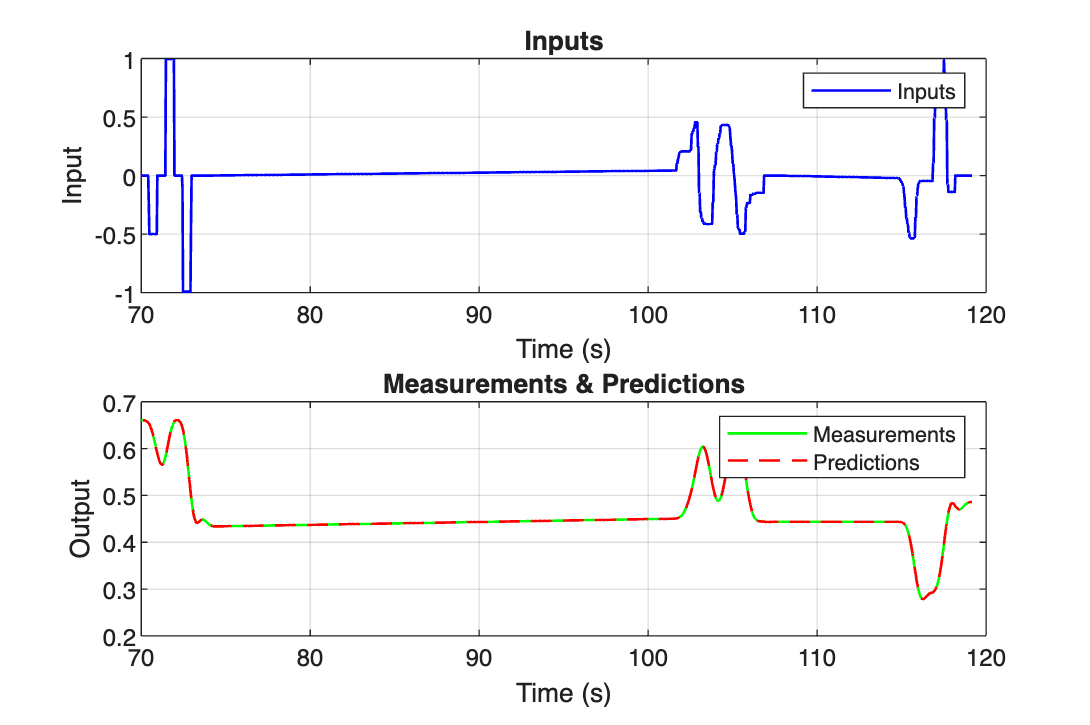


figure('Position', [100, 100, 1200, 800]);

% Plot inputs over time
subplot(2, 1, 1);
plot(time, inputs, 'b-', 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Input');
title('Inputs');
grid on;
legend('Inputs');

% Plot measurements and predictions over time
subplot(2, 1, 2);
plot(time, measurements, 'g-', 'LineWidth', 1); hold on;
plot(time(maxDelay+1:end), predictions, 'r--', 'LineWidth', 1);
xlabel('Time (s)');
ylabel('Output');
title('Measurements & Predictions');
grid on;
legend('Measurements', 'Predictions');

## PID Controller

Configure the PID controller tuning parameters.

% Select a controller type
controllerType = "PID";

% Responsiveness (0 = Slower, 1 = Faster)
responsiveness = 0.5;

% Transient Behavior (0 = Aggressive, 1 = Robust)
transientBehavior = 0.5;

% Time step for discretization (seconds)
timestep = 0.01;

%% Tuning
stateTransitionParameters = stateTransitionParameters(:).'; 
inputParameters = inputParameters(:).';

num = inputParameters;
den = [1, stateTransitionParameters];
fprintf("Transfer Function:\n\n");

Transfer Function:



fprintf("       %.6fs^2 + %.6fs + %.6f\n", inputParameters(1), inputParameters(2), inputParameters(3));

       0.001304s^2 + 0.000085s + -0.000457


fprintf("G(s) = %s\n", repmat('─',1,50));

G(s) = ──────────────────────────────────────────────────


fprintf("       s^2 + %.6fs + %.6f\n\n", stateTransitionParameters(1), stateTransitionParameters(2));

       s^2 + -1.932134s + 0.932188




%% Targets
targetOvershoot     = max(5, 50*(1 - transientBehavior));
targetSettlingTime  = 0.1 + 2.0*(1 - responsiveness);
targetRiseTime      = 0.05 + 0.5*(1 - responsiveness);

%% Initial Gains (with Kv)
switch controllerType
    case "P"
        Kp = 1.0; Ki = 0.0; Kd = 0.0; Kv = 0.0;
    case "PI"
        Kp = 1.0; Ki = 0.5; Kd = 0.0; Kv = 0.0;
    case "PID"
        Kp = 1.0; Ki = 0.5; Kd = 0.1; Kv = 0.0;
    case "PD"
        Kp = 1.0; Ki = 0.0; Kd = 0.1; Kv = 0.0;
    case "PIV"
        Kp = 1.0; Ki = 0.5; Kd = 0.0; Kv = 0.3;
    otherwise
        error("Unknown controller type: %s", controllerType);
end

theta0 = log([max(Kp, eps), max(Ki, eps), max(Kd, eps), max(Kv, eps)]);

%% Inline Tuning Objective
alphaKv = 0.8;
objective = @(theta) localObjectiveToy(theta, controllerType, ...
    responsiveness, transientBehavior, ...
    targetRiseTime, targetSettlingTime, targetOvershoot, alphaKv);

opts = optimset('Display','none');
thetaOpt = fminsearch(objective, theta0, opts);

K = exp(thetaOpt(:))'; % [Kp, Ki, Kd, Kv]
Kp = K(1); Ki = K(2); Kd = K(3); Kv = K(4);

switch controllerType
    case "P"
        Ki = 0.0; Kd = 0.0; Kv = 0.0;
    case "PI"
        Kd = 0.0; Kv = 0.0;
    case "PD"
        Ki = 0.0; Kv = 0.0;
    case "PID"
        Kv = 0.0;
    case "PIV"
        Kd = 0.0;
end

%% Step Response
[t, y, riseTime, settlingTime, overshoot] = computeStepResponse(Kp, Ki, Kd, Kv);

%% Discretization
[Kp_d, Ki_d, Kd_d, Kv_d] = continuousToDiscrete(Kp, Ki, Kd, Kv, timestep);

%% Results
fprintf("\nContinuous:\n");


Continuous:


fprintf("Kp = %.4f\n", Kp);

Kp = 1.0112


if Ki > 0, fprintf("Ki = %.4f\n", Ki); end

Ki = 1.0969


if Kd > 0, fprintf("Kd = %.4f\n", Kd); end

Kd = 25.0000


if Kv > 0, fprintf("Kv = %.4f\n", Kv); end

fprintf("\nDiscrete:\n");


Discrete:


fprintf("Kp = %.4f\n", Kp_d);

Kp = 1.0112


if Ki > 0, fprintf("Ki = %.4f\n", Ki_d); end

Ki = 0.0055


if Kd > 0, fprintf("Kd = %.4f\n", Kd_d); end

Kd = 5000.0039


if Kv > 0, fprintf("Kv = %.4f\n", Kv_d); end

fprintf("\nRise Time: %.3f seconds\n", riseTime);


Rise Time: 0.005 seconds


fprintf("Settling Time: %.3f seconds\n", settlingTime);

Settling Time: 0.145 seconds


fprintf("Overshoot: %.1f%%\n", overshoot);

Overshoot: 0.0%


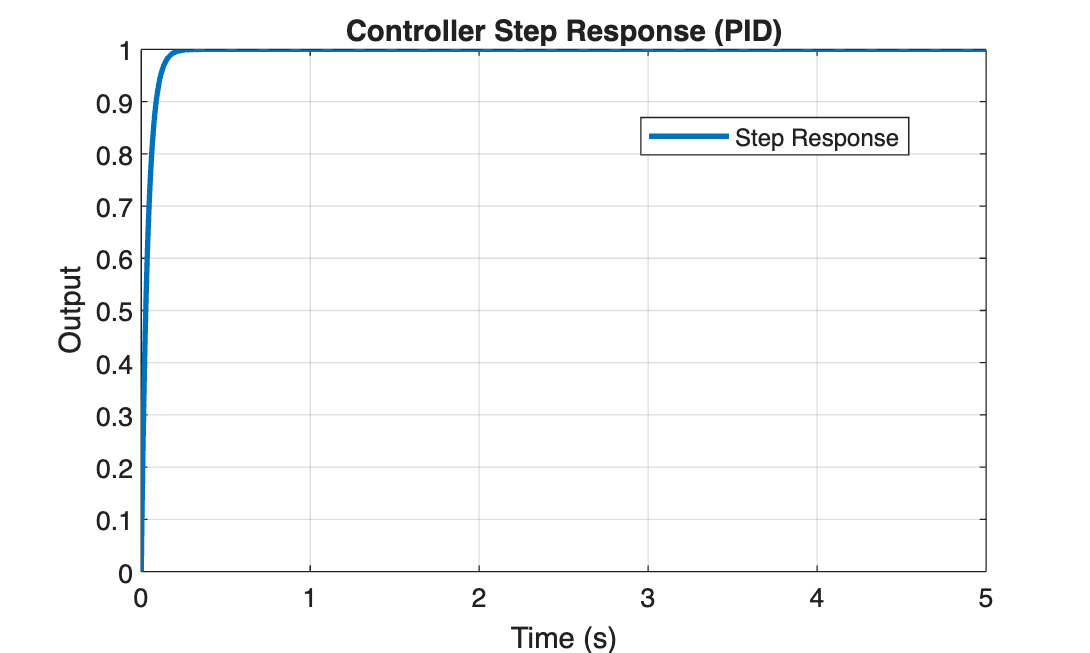


%% Plot
plotStepResponse(t, y, controllerType);


%% ————————————————————————————————————————————————————————————————
%% Helper functions

function cost = localObjectiveToy(theta, controllerType, responsiveness, transientBehavior, targetRiseTime, targetSettlingTime, targetOvershoot, alphaKv)
    Kp = exp(theta(1));
    Ki = exp(theta(2));
    Kd = exp(theta(3));
    Kv = exp(theta(4));

    switch controllerType
        case "P"
            Ki = 0; Kd = 0; Kv = 0;
        case "PI"
            Kd = 0; Kv = 0;
        case "PD"
            Ki = 0; Kv = 0;
        case "PID"
            Kv = 0;
        case "PIV"
            Kd = 0;
    end

    KpTuned = Kp * (0.5 + responsiveness);
    KiTuned = Ki * (0.5 + transientBehavior);
    KdTuned = Kd * (0.5 + responsiveness);
    KvTuned = Kv * (0.5 + transientBehavior);

    dampingBundle = KdTuned + alphaKv * KvTuned;

    cost = abs(KpTuned - targetRiseTime) ...
         + abs(KiTuned - targetSettlingTime) ...
         + abs(dampingBundle - targetOvershoot);
end

function [Kp_d, Ki_d, Kd_d, Kv_d] = continuousToDiscrete(Kp, Ki, Kd, Kv, Ts)
    Kp_d = Kp;
    Ki_d = Ki * Ts/2;
    Kd_d = Kd * 2/Ts;
    Kv_d = Kv * 2/Ts;
end

function [t, y, riseTime, settlingTime, overshoot] = computeStepResponse(Kp, Ki, Kd, Kv)
    t = linspace(0, 5, 1000);
    alpha = 0.8;
    damping = Kd + alpha*Kv;
    y = 1 - exp(-t * max(Kp, 1e-6)) .* cos(t * max(Ki, 1e-6)) .* exp(-t * max(damping, 1e-6));
    y = min(max(y, 0), 1.2);

    yFinal = y(end);
    y10 = 0.1 * yFinal;
    idxRise = find(y >= y10, 1, 'first');
    if isempty(idxRise), riseTime = 0; else, riseTime = t(idxRise); end

    tol = 0.02 * abs(yFinal);
    idxSettle = find(abs(y - yFinal) > tol, 1, 'last');
    if isempty(idxSettle), settlingTime = 0; else, settlingTime = t(idxSettle); end

    overshoot = max(0, (max(y) - yFinal) / max(yFinal, 1e-6) * 100);
end

function plotStepResponse(t, y, controllerType)
    figure('Color','w','Position',[100 100 900 540]);
    plot(t, y, 'LineWidth', 2); hold on;
    yline(1, '--', 'Setpoint', 'Alpha', 0.7);
    grid on;
    xlabel('Time (s)');
    ylabel('Output');
    title(sprintf('Controller Step Response (%s)', controllerType));
    legend('Step Response','Location','best');
end